# Lab Report 2 - Trajectory Generation and Following

**Ain Shams University, Mechatronics Engineering | Fall 2026**

The two digits give a = 7 and b = 6. Run all sections with Robotics System Toolbox and Optimization Toolbox. The final sections contain the original lab helpers and the local functions that implement the report.

clear; close all; clc
a = 7; b = 6;
fprintf('Student ID ends in %d%d. a = %d, b = %d.\n',a,b,a,b)

Student ID ends in 76. a = 7, b = 6.


## Task 1.1 | Flexible-load baseline and acceleration spectra

A lightly damped structural mode is most sensitive to acceleration near its natural frequency. Compare the four baseline profiles at 3.40 Hz. The residual is the largest absolute deflection after the move. At the design frequency, the quintic has the lowest spectrum magnitude and residual. The cubic and S-curve switch order in the measured response because damping gives later excitation greater weight.

D = 1; T = 2; dt = 0.001; q0 = 0; qf = q0 + D;
fn = 2 + 0.2*a; zeta = 0.02; t = 0:dt:T;
names = {'Cubic','Quintic','Trapezoid','S-curve'};
[cq,cv] = deal([0 0 3*D/T^2 -2*D/T^3], ...
    [0 0 0 10*D/T^3 -15*D/T^4 6*D/T^5]);
cub = polyProfile(cq,t); cub.jumps = [0 T];
qui = polyProfile(cv,t);
trp = lspbProfile(q0,qf,T,1.5*D/T,t);
[vS,aS,jS] = scurveLimitsForDuration(D,T,1/3,1/4);
scv = scurveProfile(q0,qf,vS,aS,jS,t);
profiles = {cub,qui,trp,scv};

% Prediction from the acceleration spectrum at the design frequency.
% The lightly damped oscillator is most sensitive near its mode.
spectrumAtFn = cellfun(@(p) abs(dt*sum(p.qdd.*exp(-2i*pi*fn*t))), profiles);
[~,spectrumOrder] = sort(spectrumAtFn);
fprintf('Spectrum-based order at %.2f Hz: %s\n',fn,strjoin(names(spectrumOrder),' < '))

Spectrum-based order at 3.40 Hz: Quintic < Cubic < S-curve < Trapezoid


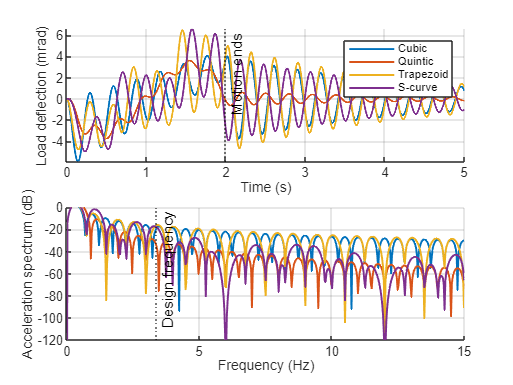


tPost = 0:dt:(T+3);
figure('Name','Task 1 - Baseline vibration and spectra')
tiledlayout(2,1,'TileSpacing','compact')
nexttile; hold on; grid on
baselineResidual = zeros(1,4);
for k = 1:4
    [baselineResidual(k),deflection] = residualVib(t,profiles{k},fn,zeta,tPost);
    plot(tPost,deflection,'LineWidth',1.3)
end
xline(T,'k:','Motion ends','HandleVisibility','off')
ylabel('Load deflection (mrad)'); xlabel('Time (s)'); legend(names)
nfft = 2^15;
freq = (0:nfft/2)/(nfft*dt);
nexttile; hold on; grid on
for k = 1:4
    A = abs(fft(profiles{k}.qdd,nfft))*dt;
    plot(freq,20*log10(A(1:nfft/2+1)+eps),'LineWidth',1.3)
end
xline(fn,'k:','Design frequency')
xlim([0 15]); ylim([-120 0])
xlabel('Frequency (Hz)'); ylabel('Acceleration spectrum (dB)')

baseline = table(string(names(:)),spectrumAtFn(:),baselineResidual(:), ...
    'VariableNames',{'Profile','SpectrumAtFn','Residual_mrad'})

baseline = 4×3 table
      Profile      SpectrumAtFn    Residual_mrad
    ___________    ____________    _____________

    "Cubic"           0.11835          4.0134   
    "Quintic"        0.015459         0.63169   
    "Trapezoid"       0.15606           4.982   
    "S-curve"         0.12416          3.9284   


## Task 1.2 | Trapezoid duration sweep

The default trapezoid has blend time T/3 and pulse separation 2T/3. Integer multiples of a natural period produce cancellation in the undamped limit. The dotted lines mark the one-pulse cancellations. The deepest dips are near 0.88, 1.76, 2.64 and 3.52 s.

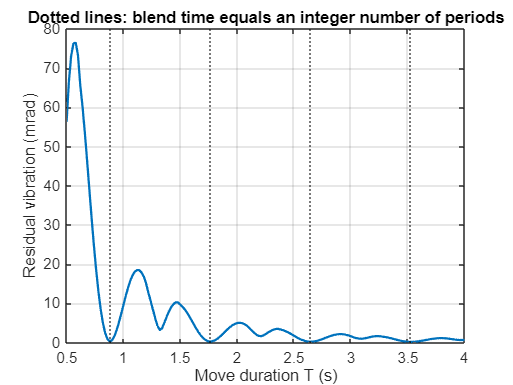

Tgrid = 0.5:0.02:4;
sweepResidual = zeros(size(Tgrid));
for k = 1:numel(Tgrid)
    Tk = Tgrid(k);
    tk = 0:dt:Tk;
    prof = lspbProfile(q0,qf,Tk,1.5*D/Tk,tk);
    sweepResidual(k) = residualVib(tk,prof,fn,zeta,0:dt:(Tk+3));
end
figure('Name','Task 1 - Trapezoid duration sweep')
plot(Tgrid,sweepResidual,'LineWidth',1.5); hold on; grid on
for k = 1:floor(4*fn/3)
    xline(3*k/fn,'k:','HandleVisibility','off')
end
xlabel('Move duration T (s)'); ylabel('Residual vibration (mrad)')
title('Dotted lines: blend time equals an integer number of periods')

## Task 1.3 | One-period blend and frequency uncertainty

Keep the tuned velocity command fixed across the frequency sweep. The tuned trapezoid wins at 3.40 Hz and the S-curve wins at +10%. The quintic is recommended across the full band because it has both the smallest worst-case residual and the lowest peak acceleration.

tb = 1/fn;
Vtuned = D/(T-tb);
tuned = lspbProfile(q0,qf,T,Vtuned,t);
robustProfiles = {tuned,qui,scv};
robustNames = {'Tuned trapezoid','Quintic','S-curve'};
fgrid = linspace(0.9*fn,1.1*fn,137);
robustResidual = zeros(numel(fgrid),3);
for k = 1:3
    for j = 1:numel(fgrid)
        robustResidual(j,k) = residualVib(t,robustProfiles{k},fgrid(j),zeta,tPost);
    end
end
[worstResidual,iworst] = max(robustResidual,[],1);
peakAcc1 = cellfun(@(p) max(abs(p.qdd)),robustProfiles);
fprintf('Tuned trapezoid blend = %.6f s, cruise = %.6f rad/s.\n',tb,Vtuned)

Tuned trapezoid blend = 0.294118 s, cruise = 0.586207 rad/s.


frequencyComparison = table(string(robustNames(:)),peakAcc1(:),robustResidual(1,:)', ...
    robustResidual(69,:)',robustResidual(end,:)',worstResidual(:),reshape(fgrid(iworst),[],1), ...
    'VariableNames',{'Profile','PeakAcceleration_rad_s2','ResidualMinus10_mrad', ...
    'ResidualDesign_mrad','ResidualPlus10_mrad','WorstBandResidual_mrad','WorstAt_Hz'})

frequencyComparison = 3×7 table
         Profile         PeakAcceleration_rad_s2    ResidualMinus10_mrad    ResidualDesign_mrad    ResidualPlus10_mrad    WorstBandResidual_mrad    WorstAt_Hz
    _________________    _______________________    ____________________    ___________________    ___________________    ______________________    __________

    "Tuned trapezoid"            1.9931                    3.1479                 0.47462                 2.8225                  3.2444              3.095   
    "Quintic"                    1.4434                   0.88066                 0.63169                0.77717                  1.2747                3.2   
    "S-curve"                       1.5                    2.3684                  3.9284    

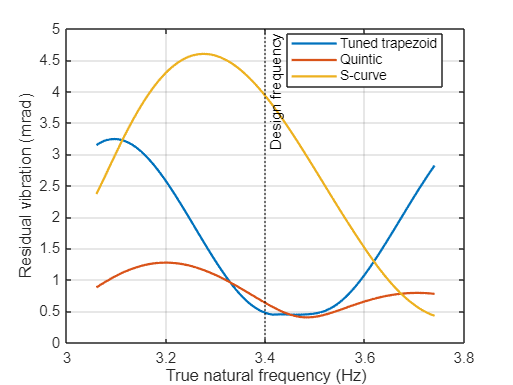

figure('Name','Task 1 - Frequency uncertainty')
plot(fgrid,robustResidual,'LineWidth',1.5); hold on; grid on
xline(fn,'k:','Design frequency','HandleVisibility','off')
xlabel('True natural frequency (Hz)'); ylabel('Residual vibration (mrad)')
legend(robustNames,'Location','best')

## Task 2.1 | Waypoint timing and peak hand acceleration

Square-root chord timing is the initial prediction because d/h^2 sets the acceleration scale for a segment of length d and duration h. The minimum-jerk curve joins the segments, so their derivatives are coupled. Chord-length timing gives the lowest peak among the fixed rules. The duration search reduces that peak by about 50.74%.

wp = [1.2 0.9 0.3+0.05*a -0.4 -1.0;
      0.2 0.9 1.2-0.03*b  1.1  0.6];
L1 = 1; L2 = 0.7; m1 = 2; m2 = 1;
planarArm = buildPlanar2R(L1,L2,m1,m2);
links = [L1 L2]; masses = [m1 m2];
Ttot = 8; nfine = 8001; nopt = 401;
chord = vecnorm(diff(wp,1,2));
starts = Ttot*[ones(1,4)/4; chord/sum(chord); sqrt(chord)/sum(sqrt(chord))];
ruleNames = ["Equal"; "Chord length"; "Square-root chord"];
% Prediction: square-root chord timing balances the d/h^2 scale.
% The joined minimum-jerk trajectory also depends on direction changes.
metrics = cell(4,1);
duration = zeros(4,4);
for k = 1:3
    duration(k,:) = starts(k,:);
    [r,tt,tw] = handPath(wp,duration(k,:),nfine);
    r.name = ruleNames(k);
    metrics{k} = waypointMetrics(r,tt,wp,tw);
end

% Epigraph variable x(5) bounds the sampled peak. Check each candidate
% on a finer grid, and retain the best valid solution found.
options = optimoptions('fmincon','Algorithm','sqp','Display','none', ...
    'MaxIterations',200,'MaxFunctionEvaluations',6000, ...
    'ConstraintTolerance',1e-8,'OptimalityTolerance',1e-8,'StepTolerance',1e-11);
[hAcceleration,exitAcceleration] = optimiseDurations(wp,starts,0,links,masses,nopt,nfine,options);
duration(4,:) = hAcceleration;
[accPath,accTime,accWayTimes] = handPath(wp,hAcceleration,nfine);
accPath.name = "Peak-acceleration optimum";
metrics{4} = waypointMetrics(accPath,accTime,wp,accWayTimes);
timingMetrics = vertcat(metrics{:});
timingMetrics = [table(duration(:,1),duration(:,2),duration(:,3),duration(:,4), ...
    'VariableNames',{'Duration1_s','Duration2_s','Duration3_s','Duration4_s'}),timingMetrics]

timingMetrics = 4×13 table
    Duration1_s    Duration2_s    Duration3_s    Duration4_s              Method               MaxWaypointMiss_mm    PeakSpeed    SpeedAtWaypoints_min    SpeedAtEnds    AccelerationAtEnds    PeakAcceleration    JerkCost    PathLength
    ___________    ___________    ___________    ___________    ___________________________    __________________    _________    ____________________    ___________    __________________    ________________    ________    __________

           2               2             2              2     

[fixedPeak,bestRule] = min(timingMetrics.PeakAcceleration(1:3));
accGain = 100*(1-timingMetrics.PeakAcceleration(4)/fixedPeak);
fprintf('Acceleration improvement over %s = %.2f%% (fmincon exit %d).\n',ruleNames(bestRule),accGain,exitAcceleration)

Acceleration improvement over Chord length = 50.74% (fmincon exit 1).


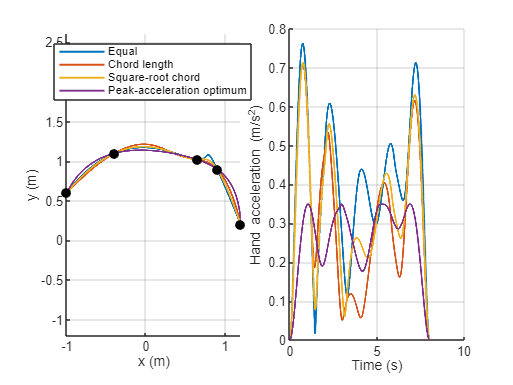


figure('Name','Task 2 - Fixed timing rules and acceleration optimum')
tiledlayout(1,2,'TileSpacing','compact')
nexttile; hold on; axis equal; grid on
for k = 1:4
    r = handPath(wp,duration(k,:),nfine);
    plot(r.q(1,:),r.q(2,:),'LineWidth',1.3)
end
plot(wp(1,:),wp(2,:),'ko','MarkerFaceColor','k','HandleVisibility','off')
xlabel('x (m)'); ylabel('y (m)'); legend(timingMetrics.Method,'Location','best')
nexttile; hold on; grid on
for k = 1:4
    [r,tt] = handPath(wp,duration(k,:),nfine);
    plot(tt,vecnorm(r.qdd),'LineWidth',1.3)
end
xlabel('Time (s)'); ylabel('Hand acceleration (m/s^2)')

## Task 2.2 | Elbow branches and peak joint torque

The shoulder gravity torque depends on the horizontal moment arms of the two links. Compare both branches on the acceleration-optimized path, then minimize the peak joint torque independently on each branch. The negative-q2 branch has less shoulder gravity torque at its peak on the acceleration-optimal path. Torque optimization favors positive q2 and gives more time to its first segment. Retiming changes both the curve between waypoints and the velocity and acceleration contributions to torque. The negative branch spends the most time on the final segment.

branches = [1 -1];
branchName = ["q2 positive";"q2 negative"];
mode = ["Acceleration optimum";"Torque optimum"];
torqueDurations = zeros(2,4);
torquePeak = zeros(2,2); torquePeakTime = zeros(2,2);
torquePeakJoint = zeros(2,2); torqueAtPeak = zeros(2,2);
postureAtPeak = zeros(4,2); gravityAtPeak = zeros(2,2);
torques = cell(2,2); torquet = cell(2,2);
for j = 1:2
    branch = branches(j);
    [torqueDurations(j,:),flag] = optimiseDurations(wp,[starts;hAcceleration], ...
        branch,links,masses,nopt,nfine,options);
    fprintf('Torque optimisation, %s (fmincon exit %d).\n',branchName(j),flag)
    for k = 1:2
        candidates = [hAcceleration;torqueDurations(j,:)];
        [r,tt] = handPath(wp,candidates(k,:),nfine);
        [q,qd,qdd,tauFast,reach] = planarDynamics(r,branch,links,masses);
        assert(all(reach >= 0),'A selected 2R path approaches or exceeds the workspace boundary.')
        tau = zeros(size(q));
        for i = 1:numel(tt)
            tau(i,:) = inverseDynamics(planarArm,q(i,:),qd(i,:),qdd(i,:));
        end
        assert(max(abs(tau-tauFast),[],'all') < 1e-7,'Planar dynamics and inverseDynamics disagree.')
        [torquePeak(j,k),ix] = max(abs(tau(:)));
        [sample,joint] = ind2sub(size(tau),ix);
        torquePeakTime(j,k) = tt(sample);
        torquePeakJoint(j,k) = joint;
        torqueAtPeak(j,k) = tau(sample,joint);
        G = inverseDynamics(planarArm,q(sample,:),[0 0],[0 0]);
        gravityAtPeak(j,k) = G(joint);
        postureAtPeak(j+2*(k-1),:) = rad2deg(q(sample,:));
        torques{j,k} = tau; torquet{j,k} = tt;
    end
end

Torque optimisation, q2 positive (fmincon exit 1).
Torque optimisation, q2 negative (fmincon exit 2).


allTorqueDurations = [repmat(hAcceleration,2,1);torqueDurations];
torqueSummary = table(repelem(mode,2),repmat(branchName,2,1),allTorqueDurations, ...
    torquePeak(:),torquePeakTime(:),torquePeakJoint(:),torqueAtPeak(:),gravityAtPeak(:),postureAtPeak, ...
    'VariableNames',{'Timing','Branch','Durations_s','Peak_Nm','PeakTime_s','PeakJoint', ...
    'SignedTorque_Nm','GravityPart_Nm','Posture_deg'})

torqueSummary = 4×9 table
            Timing               Branch                      Durations_s                  Peak_Nm    PeakTime_s    PeakJoint    SignedTorque_Nm    GravityPart_Nm       Posture_deg    
    ______________________    _____________    _______________________________________    _______    __________    _________    _______________    ______________    __________________

    "Acceleration optimum"    "q2 positive"    2.9369    0.55121     1.7016     2.8103    20.373       1.664           1             20.373            20.081        -12.935     86.723
    "Acceleration optimum"    "q2 negative"    2.9369    0.55121     1.7016     2.8103     20.02       7.072       

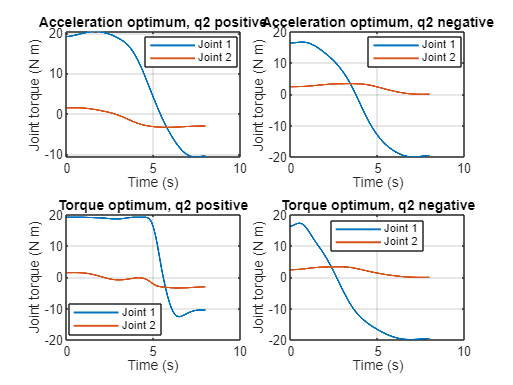

figure('Name','Task 2 - Joint torques')
tiledlayout(2,2,'TileSpacing','compact')
for k = 1:2
    for j = 1:2
        nexttile; plot(torquet{j,k},torques{j,k},'LineWidth',1.3); grid on
        title(mode(k) + ", " + branchName(j))
        xlabel('Time (s)'); ylabel('Joint torque (N m)')
        legend('Joint 1','Joint 2','Location','best')
    end
end

## Task 3 | UR5e path, branch continuity and joint-speed limits

The tool follows a horizontal line 0.54 m long at 232 degrees while rotating 45 degrees about its local x-axis. For each path sample, the largest absolute joint derivative sets the path-speed limit of 1/max(`dq/ds`). The Jacobian's smallest singular value measures worst-direction conditioning. Peak joint demand also depends on the commanded tool twist. The limiting sequence is 3, 2, 1, 6. The speed reaches its minimum near s = 0.713 as joint 6 makes its largest demand. The singular value reaches its minimum later, near s = 0.853, because the direction of the commanded twist matters as well as the Jacobian conditioning.

ur5 = loadrobot('universalUR5e','DataFormat','row','Gravity',[0 0 -9.81]);
qA = [0 -pi/2 pi/2 -pi/2 -pi/2 0];
ee = 'tool0';
T0 = getTransform(ur5,qA,ee);
p0 = T0(1:3,4); R0 = T0(1:3,1:3);
L = 0.40 + 0.02*a;
theta = 220 + 2*b;
s = linspace(0,1,151); ds = s(2)-s(1);
pPath = p0 + L*[cosd(theta);sind(theta);0]*s;
R1 = R0*axang2rotm([1 0 0 pi/4]); % post-multiply for the local x-axis
Rpath = rottraj(R0,R1,[0 1],s); % SLERP on a uniform path-parameter grid
ik = inverseKinematics('RigidBodyTree',ur5,'SolverAlgorithm','LevenbergMarquardt');
ik.SolverParameters.MaxIterations = 500;
ik.SolverParameters.AllowRandomRestart = false;
ik.SolverParameters.SolutionTolerance = 1e-10;
ikWeights = ones(1,6);
q = zeros(numel(s),6); qPrev = qA;
positionError = zeros(size(s)); orientationError = zeros(size(s)); sigmaMin = zeros(size(s));
for k = 1:numel(s)
    target = [Rpath(:,:,k) pPath(:,k); 0 0 0 1];
    [qPrev,info] = ik(ee,target,ikWeights,qPrev);
    q(k,:) = qPrev;
    achieved = getTransform(ur5,qPrev,ee);
    positionError(k) = norm(achieved(1:3,4)-target(1:3,4));
    er = rotm2axang(target(1:3,1:3)'*achieved(1:3,1:3));
    orientationError(k) = er(4);
    singularValues = svd(geometricJacobian(ur5,qPrev,ee));
    sigmaMin(k) = singularValues(end);
    if positionError(k) > 1e-6 || orientationError(k) > 1e-6
        error('IK pose accuracy at s=%.6f, status %s.',s(k),string(info.Status))
    end
end
q = unwrap(q,[],1);
jointStep = max(abs(diff(q,1,1)),[],1);
dqds = gradient(q',ds)';
[maxDerivative,limitingJoint] = max(abs(dqds),[],2);
sdotMax = 1./maxDerivative; % joint limit is 1 rad/s for each joint
switchIndex = find(diff(limitingJoint) ~= 0)+1;
[slowest,imin] = min(sdotMax);
[smallestSigma,isig] = min(sigmaMin);
fprintf('Largest adjacent joint step %.5f deg. Pose errors %.3g m and %.3g rad.\n', ...
    rad2deg(max(jointStep)),max(positionError),max(orientationError))

Largest adjacent joint step 0.91463 deg. Pose errors 1.9e-08 m and 2.11e-08 rad.


fprintf('Minimum path speed %.5f 1/s at s=%.5f. Minimum sigma %.5f at s=%.5f.\n', ...
    slowest,s(imin),smallestSigma,s(isig))

Minimum path speed 0.41764 1/s at s=0.71333. Minimum sigma 0.11096 at s=0.85333.


switches = table(reshape(s(switchIndex-1),[],1),reshape(s(switchIndex),[],1), ...
    limitingJoint(switchIndex-1),limitingJoint(switchIndex), ...
    'VariableNames',{'Before_s','After_s','BeforeJoint','AfterJoint'})

switches = 3×4 table
    Before_s    After_s    BeforeJoint    AfterJoint
    ________    _______    ___________    __________

       0.14     0.14667         3             2     
    0.14667     0.15333         2             1     
       0.66     0.66667         1             6     


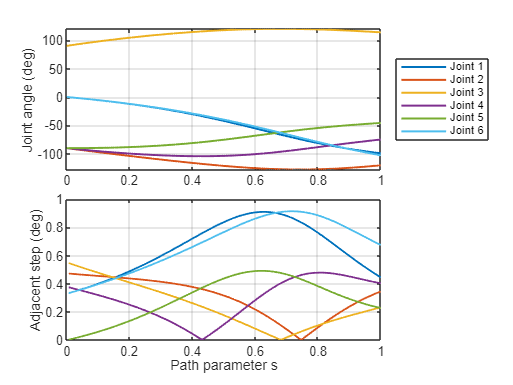

figure('Name','Task 3 - UR5e joint-path continuity')
tiledlayout(2,1,'TileSpacing','compact')
nexttile; plot(s,rad2deg(q),'LineWidth',1.3); grid on
ylabel('Joint angle (deg)'); legend("Joint " + (1:6),'Location','eastoutside')
nexttile; plot(s(2:end),rad2deg(abs(diff(q,1,1))),'LineWidth',1.2); grid on
xlabel('Path parameter s'); ylabel('Adjacent step (deg)')

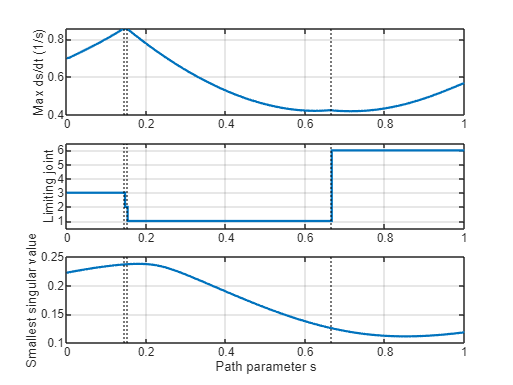

figure('Name','Task 3 - Path-speed limit and Jacobian conditioning')
tiledlayout(3,1,'TileSpacing','compact')
ax = gobjects(3,1);
ax(1) = nexttile; plot(s,sdotMax,'LineWidth',1.5); grid on
ylabel('Max ds/dt (1/s)')
ax(2) = nexttile; stairs(s,limitingJoint,'LineWidth',1.5); grid on
ylabel('Limiting joint'); yticks(1:6); ylim([0.5 6.5])
ax(3) = nexttile; plot(s,sigmaMin,'LineWidth',1.5); grid on
xlabel('Path parameter s'); ylabel('Smallest singular value')
linkaxes(ax,'x'); xlim([0 1])
for k = 1:numel(ax)
    xline(ax(k),s(switchIndex),'k:','HandleVisibility','off');
end

jointPath = table(s(:),q,dqds,sdotMax,limitingJoint,sigmaMin(:),positionError(:), ...
    orientationError(:),'VariableNames',{'s','q_rad','dq_ds','MaxPathSpeed_per_s', ...
    'LimitingJoint','SigmaMin','PositionError_m','OrientationError_rad'});
samples = unique([1;switchIndex(:);imin;isig;numel(s)]);
pathLimitSummary = jointPath(samples,{'s','MaxPathSpeed_per_s','LimitingJoint','SigmaMin'})

pathLimitSummary = 7×4 table
       s       MaxPathSpeed_per_s    LimitingJoint    SigmaMin
    _______    __________________    _____________    ________

          0         0.69904                3          0.22236 
    0.14667           0.856                2          0.23702 
    0.15333         0.85472                1          0.23734 
    0.66667         0.42202                6          0.12516 
    0.71333         0.41764                6          0.11879 
    0.85333         0.45661                6          0.11096 
          1         0.56549                6          0.11805 


## Local functions added for this report

Local functions for the lab tasks.

function [residual,deflection] = residualVib(t,profile,fn,zeta,tSim)
[qLoad,qMotor] = flexibleLoadResponse(t,profile,fn,zeta,tSim);
deflection = 1e3*(qLoad-qMotor);
afterMotion = tSim > t(end)+1e-10;
residual = max(abs(deflection(afterMotion)));
end

function [r,t,tw] = handPath(wp,h,N)
tw = [0 cumsum(h(:)')];
[q,qd,qdd,~,~,~,t] = minjerkpolytraj(wp,tw,N);
r = struct('name',"",'q',q,'qd',qd,'qdd',qdd);
end

function [hBest,flagBest] = optimiseDurations(wp,starts,branch,links,masses,nopt,nfine,opts)
bestCost = Inf;
hBest = [];
flagBest = NaN;
for k = 1:size(starts,1)
    h0 = starts(k,:);
    [v0,reach0] = sampledCost(wp,h0,nopt,branch,links,masses);
    if any(reach0 < 0), continue, end
    x0 = [h0 max(v0)*1.001]';
    [x,~,flag] = fmincon(@(x) x(5),x0,[],[],[1 1 1 1 0],8, ...
        [0.5 0.5 0.5 0.5 0]',[6.5 6.5 6.5 6.5 Inf]', ...
        @(x) peakConstraints(x,wp,nopt,branch,links,masses),opts);
    h = x(1:4)';
    [v,reach] = sampledCost(wp,h,nfine,branch,links,masses);
    if abs(sum(h)-8) < 1e-7 && min(h) >= 0.5-1e-9 && all(reach >= -1e-7) && max(v) < bestCost
        bestCost = max(v);
        hBest = h;
        flagBest = flag;
    end
end
assert(~isempty(hBest),'The timing optimisation did not return a feasible trajectory.')
end

function [c,ceq] = peakConstraints(x,wp,N,branch,links,masses)
[v,reach] = sampledCost(wp,x(1:4),N,branch,links,masses);
c = [v(:)-x(5); -reach(:)];
ceq = [];
end

function [v,reach] = sampledCost(wp,h,N,branch,links,masses)
r = handPath(wp,h,N);
reach = [];
if branch == 0
    v = vecnorm(r.qdd);
else
    [~,~,~,tau,reach] = planarDynamics(r,branch,links,masses);
    v = abs(tau(:));
end
end

function [q,qd,qdd,tau,reach] = planarDynamics(r,branch,lengths,masses)
L1 = lengths(1); L2 = lengths(2);
m1 = masses(1); m2 = masses(2);
p = r.q;
radius2 = sum(p.^2,1);
rawC2 = (radius2-L1^2-L2^2)/(2*L1*L2);
reach = (0.9999-abs(rawC2))';
% Project infeasible trial points just inside the workspace. The inequality
% above excludes those trials and avoids NaNs during finite differences.
clippedC2 = min(max(rawC2,-1+1e-8),1-1e-8);
validRadius = sqrt(L1^2+L2^2+2*L1*L2*clippedC2);
p = p.*(validRadius./max(sqrt(radius2),eps));
q = ik2R(p,L1,L2,branch);
q1 = q(:,1); q2 = q(:,2);
c1 = cos(q1); s1 = sin(q1); c12 = cos(q1+q2); s12 = sin(q1+q2);
c2 = cos(q2); s2 = sin(q2);
j11 = -L1*s1-L2*s12; j12 = -L2*s12;
j21 = L1*c1+L2*c12; j22 = L2*c12;
detJ = L1*L2*s2;
vx = r.qd(1,:)'; vy = r.qd(2,:)';
w1 = (j22.*vx-j12.*vy)./detJ;
w2 = (-j21.*vx+j11.*vy)./detJ;
qd = [w1 w2];
w12 = w1+w2;
ax = r.qdd(1,:)' + L1*c1.*w1.^2 + L2*c12.*w12.^2;
ay = r.qdd(2,:)' + L1*s1.*w1.^2 + L2*s12.*w12.^2;
dd1 = (j22.*ax-j12.*ay)./detJ;
dd2 = (-j21.*ax+j11.*ay)./detJ;
qdd = [dd1 dd2];
% The supplied rod inertias m L^2/3 are at the link-end frames.
I1 = m1*L1^2/12; I2 = m2*L2^2/12; % shift to the centers of mass
M22 = I2+m2*(L2/2)^2;
M12 = M22 + m2*L1*L2/2*c2;
M11 = I1+I2+m1*(L1/2)^2+m2*(L1^2+(L2/2)^2+L1*L2*c2);
k = m2*L1*L2/2*s2;
G1 = 9.81*((m1*L1/2+m2*L1)*c1+m2*L2/2*c12);
G2 = 9.81*m2*L2/2*c12;
tau = [M11.*dd1+M12.*dd2-k.*w2.*(2*w1+w2)+G1, ...
       M12.*dd1+M22*dd2+k.*w1.^2+G2];
end

## Helpers from Trajectory_Lab.mlx

All nine supplied helper definitions below are reused without changes.

function prof = polyProfile(a, t)
% Evaluate a polynomial with ascending coefficients a and its first three
% derivatives on the time vector t.
p = flip(a(:)');
pd = polyder(p);  pdd = polyder(pd);  pddd = polyder(pdd);
prof = struct('t', t, 'q', polyval(p, t), 'qd', polyval(pd, t), ...
    'qdd', polyval(pdd, t), 'qddd', polyval(pddd, t) .* ones(size(t)), 'jumps', []);
end

function prof = lspbProfile(q0, qf, T, V, t)
% Trapezoidal velocity profile (linear segment with parabolic blends) of
% duration T and cruise velocity V, sampled at t.
D = abs(qf - q0);  sgn = sign(qf - q0) + (qf == q0);  V = abs(V);
if V <= D/T || V > 2*D/T * (1 + 1e-12)
    error('Cruise velocity must satisfy D/T < V <= 2D/T (here %.3f < V <= %.3f).', D/T, 2*D/T);
end
tb = (V*T - D) / V;  a = V / tb;
[q, qd, qdd] = deal(zeros(size(t)));
i1 = t < tb;  i3 = t > T - tb;  i2 = ~i1 & ~i3;
q(i1) = 0.5*a*t(i1).^2;              qd(i1) = a*t(i1);         qdd(i1) = a;
q(i2) = V*(t(i2) - tb/2);            qd(i2) = V;
q(i3) = D - 0.5*a*(T - t(i3)).^2;    qd(i3) = a*(T - t(i3));   qdd(i3) = -a;
prof = struct('t', t, 'q', q0 + sgn*q, 'qd', sgn*qd, 'qdd', sgn*qdd, ...
    'qddd', zeros(size(t)), 'jumps', unique([0 tb T-tb T]));
end

function [vmax, amax, jmax] = scurveLimitsForDuration(D, T, alpha, beta)
% Limits for which the double-S profile over distance D lasts exactly T,
% with acceleration time alpha*T and jerk time beta*alpha*T (alpha, beta <= 1/2).
vmax = D / ((1 - alpha) * T);
amax = D / (alpha * (1 - alpha) * (1 - beta) * T^2);
jmax = D / (alpha^2 * beta * (1 - alpha) * (1 - beta) * T^3);
end

function prof = scurveProfile(q0, qf, vmax, amax, jmax, t)
% Rest-to-rest jerk-limited (double-S) profile, Biagiotti and Melchiorri
% (2008), section 3.4. If t is empty, a grid over the full duration is used.
D = abs(qf - q0);  sgn = sign(qf - q0) + (qf == q0);
if vmax * jmax >= amax^2
    Tj = amax / jmax;  Ta = Tj + vmax / amax;     % amax is reached
else
    Tj = sqrt(vmax / jmax);  Ta = 2 * Tj;         % amax is not reached
end
Tv = D / vmax - Ta;
if Tv < 0                                         % vmax is not reached
    Tv = 0;
    if D >= 2 * amax^3 / jmax^2
        Tj = amax / jmax;  Ta = Tj/2 + sqrt((Tj/2)^2 + D/amax);
    else
        Tj = (D / (2 * jmax))^(1/3);  Ta = 2 * Tj;
    end
end
Ttot = 2 * Ta + Tv;
if isempty(t), t = linspace(0, Ttot, 2001); end
jerk = jmax * [1 0 -1 0 -1 0 1];
dur  = [Tj, Ta - 2*Tj, Tj, Tv, Tj, Ta - 2*Tj, Tj];
[q, qd, qdd, qddd] = integrateJerk(jerk, dur, t);
prof = struct('t', t, 'q', q0 + sgn*q, 'qd', sgn*qd, 'qdd', sgn*qdd, 'qddd', sgn*qddd, ...
    'jumps', [], 'phases', struct('Tj', Tj, 'Ta', Ta, 'Tv', Tv, 'T', Ttot));
end

function [q, qd, qdd, qddd] = integrateJerk(jerk, dur, t)
% Exact integration of a piecewise-constant jerk profile starting at rest.
keep = dur > 1e-12;
jerk = jerk(keep);  dur = dur(keep);
n = numel(dur);
edges = [0 cumsum(dur)];
state = zeros(n + 1, 3);                          % [p v a] at the start of each segment
for k = 1:n
    h = dur(k);  j = jerk(k);  s = state(k, :);
    state(k + 1, :) = [s(1) + s(2)*h + s(3)*h^2/2 + j*h^3/6, s(2) + s(3)*h + j*h^2/2, s(3) + j*h];
end
tc = min(max(t, 0), edges(end));
seg = discretize(tc, edges);
h = tc - edges(seg);
s = state(seg, :);  j = jerk(seg);
q    = s(:, 1)' + s(:, 2)'.*h + s(:, 3)'.*h.^2/2 + j.*h.^3/6;
qd   = s(:, 2)' + s(:, 3)'.*h + j.*h.^2/2;
qdd  = s(:, 3)' + j.*h;
qddd = j;
end

function [qLoad, qMotor] = flexibleLoadResponse(t, prof, fn, zeta, tSim)
% Load position of a spring-damper connected load whose motor follows prof.
wn = 2 * pi * fn;
qm  = griddedInterpolant(t, prof.q, 'linear', 'nearest');
qdm = griddedInterpolant(t, prof.qd, 'linear', 'nearest');
f = @(tt, x) [x(2); wn^2*(qm(tt) - x(1)) + 2*zeta*wn*(qdm(tt) - x(2))];
[~, x] = ode45(f, tSim, [prof.q(1); 0], odeset('RelTol', 1e-8, 'AbsTol', 1e-10, 'MaxStep', 1e-3));
qLoad = x(:, 1)';
qMotor = qm(tSim);
end

function tbl = waypointMetrics(res, tt, wp, tw)
% Accuracy and smoothness measures for multi-waypoint trajectories.
n = numel(res);  dtt = tt(2) - tt(1);
iw = round(tw(2:end-1) / dtt) + 1;
[wpErr, vMax, aMax, vMinVia, vEnd, aEnd, jerkCost, len] = deal(zeros(n, 1));
for k = 1:n
    Q = res(k).q;
    dist = zeros(1, size(wp, 2));
    for m = 1:size(wp, 2), dist(m) = min(vecnorm(Q - wp(:, m))); end
    wpErr(k)    = 1e3 * max(dist);
    vMax(k)     = max(vecnorm(res(k).qd));
    aMax(k)     = max(vecnorm(res(k).qdd));
    vMinVia(k)  = min(vecnorm(res(k).qd(:, iw)));
    vEnd(k)     = max(vecnorm(res(k).qd(:, [1 end])));
    aEnd(k)     = max(vecnorm(res(k).qdd(:, [1 end])));
    jerkCost(k) = trapz(tt, sum(gradient(res(k).qdd, dtt).^2, 1));
    len(k)      = sum(vecnorm(diff(Q, 1, 2)));
end
tbl = table([res.name]', wpErr, vMax, vMinVia, vEnd, aEnd, aMax, jerkCost, len, 'VariableNames', ...
    {'Method', 'MaxWaypointMiss_mm', 'PeakSpeed', 'SpeedAtWaypoints_min', 'SpeedAtEnds', ...
    'AccelerationAtEnds', 'PeakAcceleration', 'JerkCost', 'PathLength'});
end

function robot = buildPlanar2R(L1, L2, m1, m2)
% 2R planar arm (standard DH, frames at the link ends) with thin-rod
% inertias, moving in the x-y plane with gravity along -y.
robot = rigidBodyTree('DataFormat', 'row', 'MaxNumBodies', 2);
robot.Gravity = [0 -9.81 0];
lengths = [L1 L2];  masses = [m1 m2];  parent = 'base';
for i = 1:2
    body = rigidBody(sprintf('link%d', i));
    joint = rigidBodyJoint(sprintf('q%d', i), 'revolute');
    setFixedTransform(joint, [lengths(i) 0 0 0], 'dh');
    body.Joint = joint;
    body.Mass = masses(i);
    body.CenterOfMass = [-lengths(i)/2 0 0];
    body.Inertia = [0, masses(i)*lengths(i)^2/3, masses(i)*lengths(i)^2/3, 0, 0, 0];
    addBody(robot, body, parent);
    parent = body.Name;
end
end

function q = ik2R(p, L1, L2, elbow)
% Closed-form IK of the 2R arm for points p (2 x N). elbow = +1 or -1 picks
% the branch. Unreachable points return NaN. Output is N x 2, with q1
% unwrapped for continuity.
c2 = (sum(p.^2, 1) - L1^2 - L2^2) / (2 * L1 * L2);
bad = abs(c2) > 1;
s2 = elbow * sqrt(max(0, 1 - c2.^2));
q2 = atan2(s2, c2);
q1 = atan2(p(2, :), p(1, :)) - atan2(L2 * s2, L1 + L2 * c2);
q1(~bad) = unwrap(q1(~bad));
q = [q1; q2]';
q(bad, :) = NaN;
end